## Example #1 : convex hull of random 2D point set

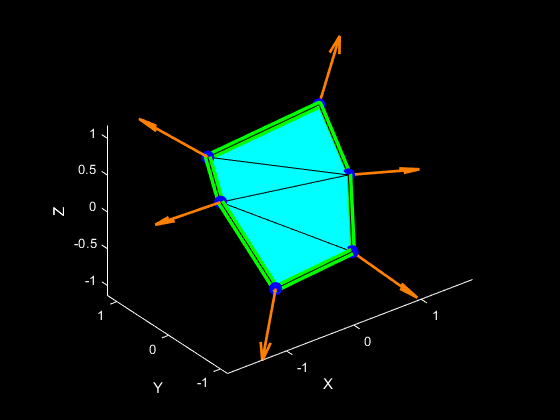

n = 32;
V = 2*(rand(n,2)-0.5);
H_raw = convhull(V);
V = cat(2,V,zeros(size(V,1),1));        

Rmx = @(theta)[1 0          0;
               0 cos(theta) -sin(theta);
               0 sin(theta) cos(theta)];

V = (Rmx(0.25*pi)*V')'; % pi/4 rotation around X axe, to check real 3D
V = V(unique(H_raw,'stable'),:);
V = V([end,end-1,1,2:end-2],:); % disorder

[C,T,N] = discrete_contour_mesh_patch(V);

figure;
plot3(C(:,1),C(:,2),C(:,3),'bo','LineWidth',4,'MarkerSize',6,'MarkerFaceColor', [0 0 1],'MarkerEdgeColor', [0 0 1]), hold on;
line(cat(1,C(:,1),C(1,1)),cat(1,C(:,2),C(1,2)),cat(1,C(:,3),C(1,3)),'Color',[0 1 0],'LineWidth',6), hold on;
quiver3(C(:,1),C(:,2),C(:,3),N(:,1),N(:,2),N(:,3),'Color',[1 0.5 0],'Linewidth',2), hold on;
trisurf(T,C(:,1),C(:,2),C(:,3)), shading faceted, hold on;
colormap([0 1 1]);        
xlabel('X'), ylabel('Y'), zlabel('Z');
axis equal, axis tight;
set(gcf,'Color',[0 0 0]), set(gca, 'Color', [0 0 0], 'XColor', [1 1 1], 'YColor', [1 1 1], 'ZColor', [1 1 1]);
view(3);

## Example #2 : 2D discrete ellipse

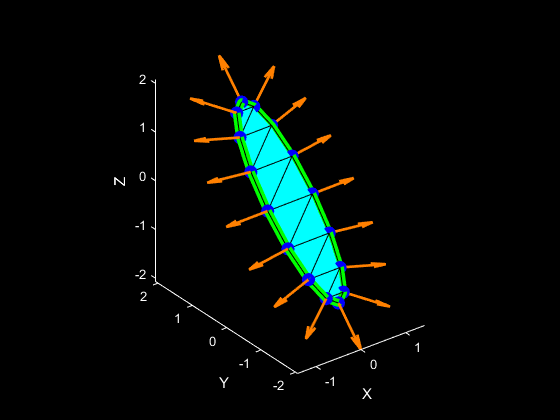

n = 16;
angl_step = 2*pi/n;
alpha = 0:angl_step:2*pi-angl_step;
X = 0.5*cos(alpha)';
Y = 2*sin(alpha)';
V = cat(2,X,Y);
H_raw = convhull(V);
V = cat(2,V,zeros(size(V,1),1));        

Rmx = @(theta)[1 0          0;
               0 cos(theta) -sin(theta);
               0 sin(theta) cos(theta)];

V = (Rmx(0.25*pi)*V')'; % pi/4 rotation around X axe, to check real 3D
V = V(unique(H_raw,'stable'),:);
V = V([end,end-1,1,2:end-2],:); % disorder

[C,T,N] = discrete_contour_mesh_patch(V);

figure;
plot3(C(:,1),C(:,2),C(:,3),'bo','LineWidth',4,'MarkerSize',6,'MarkerFaceColor', [0 0 1],'MarkerEdgeColor', [0 0 1]), hold on;
line(cat(1,C(:,1),C(1,1)),cat(1,C(:,2),C(1,2)),cat(1,C(:,3),C(1,3)),'Color',[0 1 0],'LineWidth',6), hold on;
quiver3(C(:,1),C(:,2),C(:,3),N(:,1),N(:,2),N(:,3),'Color',[1 0.5 0],'Linewidth',2), hold on;
trisurf(T,C(:,1),C(:,2),C(:,3)), shading faceted, hold on;
colormap([0 1 1]);        
xlabel('X'), ylabel('Y'), zlabel('Z');
axis equal, axis tight;
set(gcf,'Color',[0 0 0]), set(gca, 'Color', [0 0 0], 'XColor', [1 1 1], 'YColor', [1 1 1], 'ZColor', [1 1 1]);
view(3);

## Example #3 : 3D 'flower' test

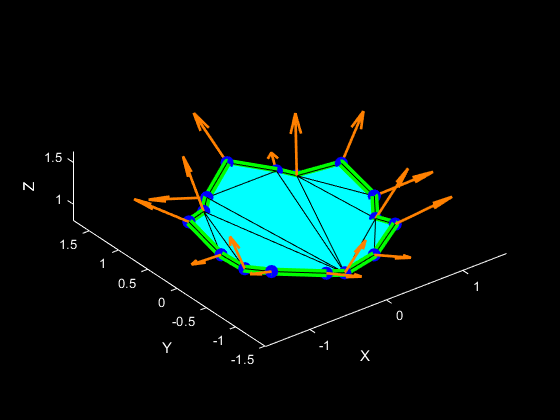

n = 16;
angl_step = 2*pi/n;
alpha = 0:angl_step:2*pi-angl_step;
X = cos(alpha)';
Y = sin(alpha)';
R = sqrt(X.^2 + Y.^2);
X = X + (0.2*R.*sin(3*alpha)'.*cos(3*alpha)');
Y = Y + (0.2*R.*sin(3*alpha)'.*sin(3*alpha)');
Z = sqrt(X.^2 + Y.^2);
V = cat(2,X,Y,Z);

V = V([end,end-1,1,2:end-2],:); % disorder

[C,T,N] = discrete_contour_mesh_patch(V);

figure;
plot3(C(:,1),C(:,2),C(:,3),'bo','LineWidth',4,'MarkerSize',6,'MarkerFaceColor', [0 0 1],'MarkerEdgeColor', [0 0 1]), hold on;
line(cat(1,C(:,1),C(1,1)),cat(1,C(:,2),C(1,2)),cat(1,C(:,3),C(1,3)),'Color',[0 1 0],'LineWidth',6), hold on;
quiver3(C(:,1),C(:,2),C(:,3),N(:,1),N(:,2),N(:,3),'Color',[1 0.5 0],'Linewidth',2), hold on;
trisurf(T,C(:,1),C(:,2),C(:,3)), shading faceted, hold on;
colormap([0 1 1]);        
xlabel('X'), ylabel('Y'), zlabel('Z');
axis equal, axis tight;
set(gcf,'Color',[0 0 0]), set(gca, 'Color', [0 0 0], 'XColor', [1 1 1], 'YColor', [1 1 1], 'ZColor', [1 1 1]);
view(3);